# **Bacteria Growth Rate: Image Analysis**

## **Physical Biology of the Cell: Day 1 (March 25, 2019)**

## **Introduction to MATLAB**

What does it look like when you start MATLAB? What are the different windows? What is a live script?

What is a variable? What is a vector? Basic vector operations. (addition, multiplication, how do you put vectors together to make a matrix, call an element from a vector). What is an image?

a = 3 %semicolon to suppress output

a = 3

b = a*2

b = 6


c = [1 2 3]

c =      1     2     3


d = 2*c

d =      2     4     6


e = c(1)

e = 1


f = [1 2 3; 3 4 5]

f =      1     2     3
     3     4     5


g = 2*f

g =      2     4     6
     6     8    10


h = f > 3

h = 2×3 logical array
   0   0   0
   0   1   1


h = f(f>3)

h =      4
     5


**How to load an image:**

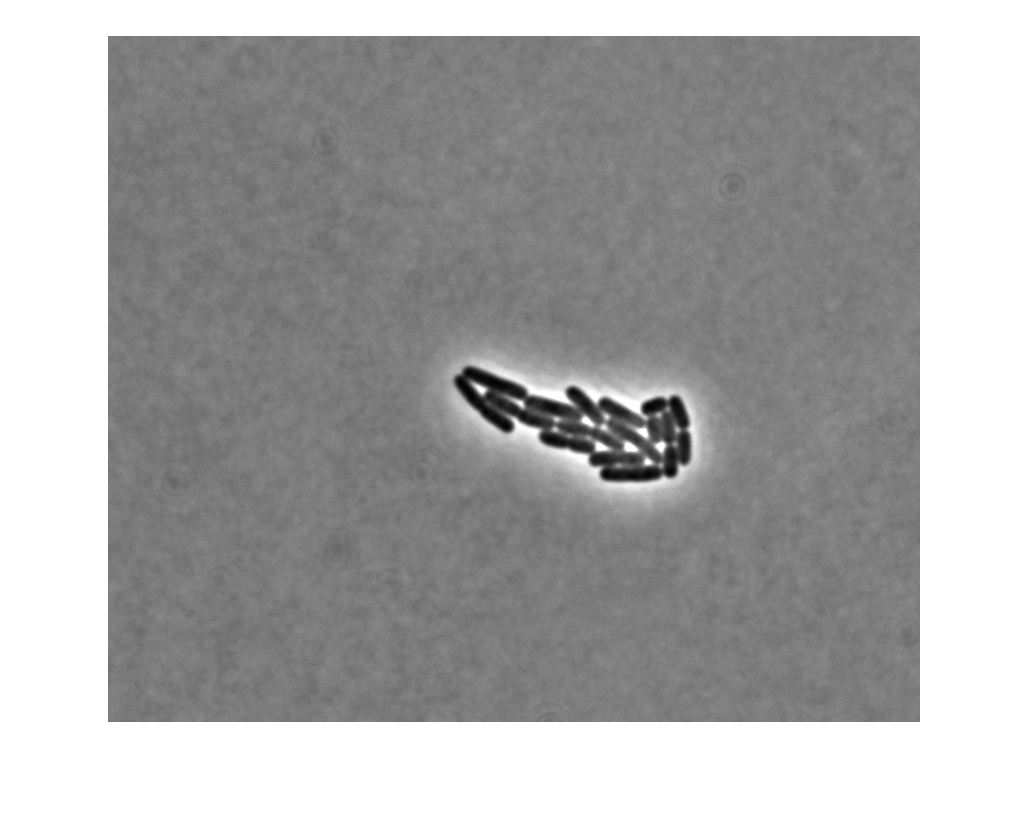

image  = imread('colony_growth/EcoliGrowth14.tif');
imshow(image,[])

**How to threshold:**

Thresholding is one of the simplest image processing techniques, and it turns a greyscale image into a binary image by individually determining which pixels become 0s or 1s. This is done by using a comparison value (the threshold), and all values larger than the threshold become a 1 and all values smaller are assigned a 0. Here, we are demonstrating a manual technique, but there are more sophisticated binarization algorithms, such as **Otsu Thresholding**. In MATLAB, This is implemented with the graythresh function.

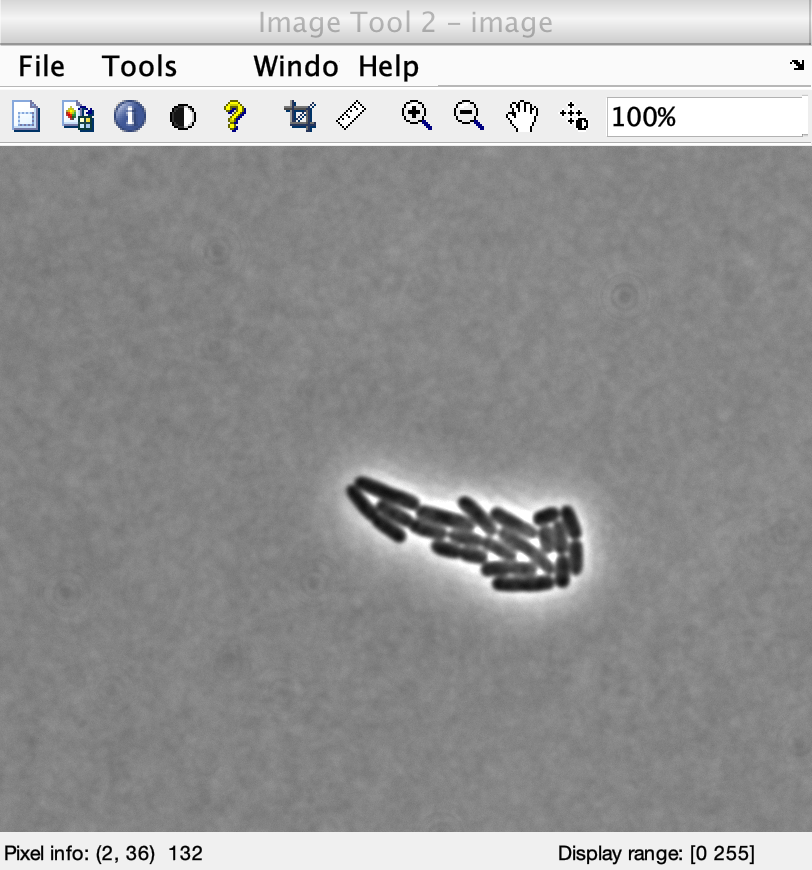

% Inspect your image to get a range of pixel intensities
imtool(image)

max(image(:))

ans = uint8
255

min(image(:))

ans = uint8
16

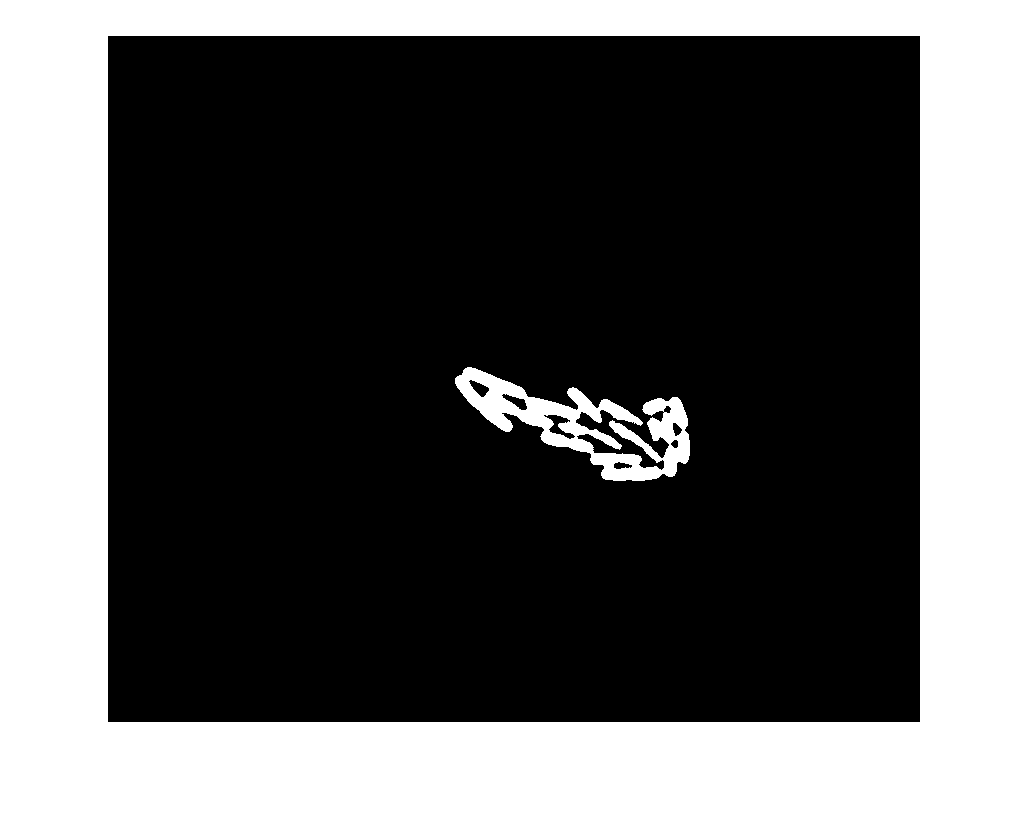


% Manually set a pixel intensity value.
threshold = 100;

image_threshold = image < threshold;

imshow(image_threshold)

**How to segment and extract useful information:**

Image segementation is used to break images down into multiple pieces to simplify the representation of the data. Then images can be analyzed to extract quantities like boundaries and objects in images. 

area = sum(image_threshold(:))

area = 9456

**How to plot data:**

Create a plot of cell area over time! 

Let's introduce the idea of pseudocode for planning out what we'd like our script to look like. What's the approach for our analysis? How do we need to structure our loop/functions/etc. to get the data we need? 

Some questions to ask: What data are we starting with? What data do we need to end up with? What functions/approaches do I have in my toolbox?

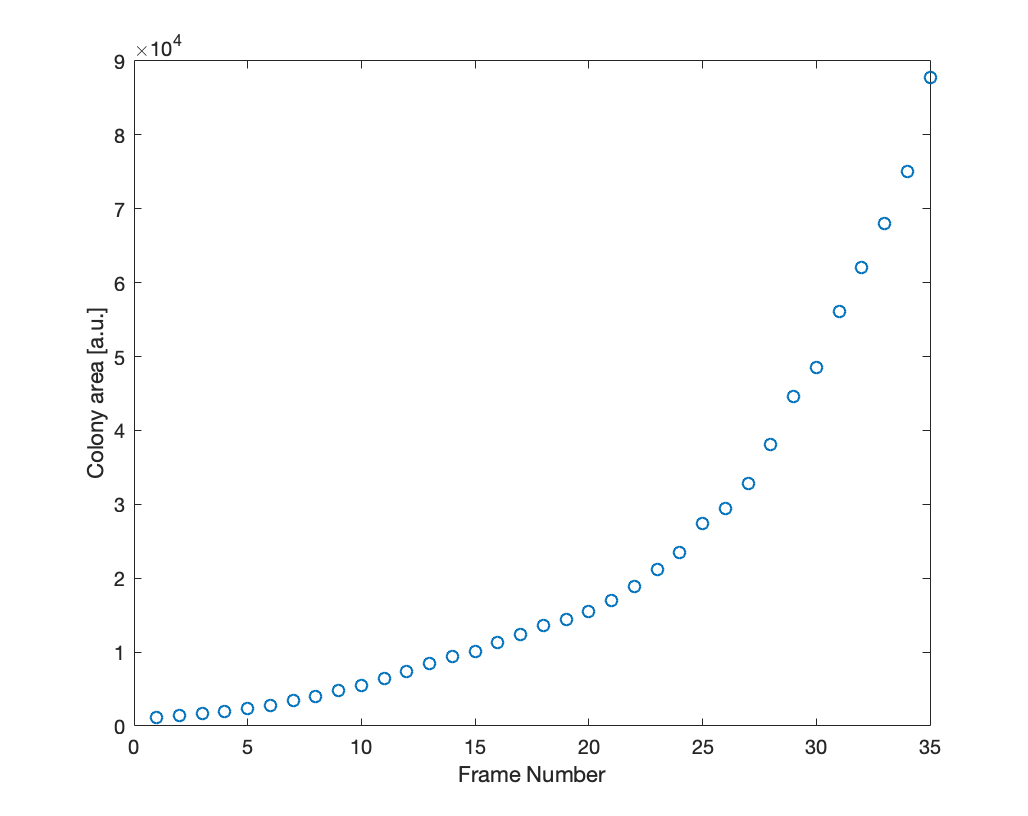

% first create a for loop to go through all the images. what's the strategy here?

% step 1. load all images in a folder
%cd colony_growth/
images = dir('*.tif');
threshold = 100;
area_list = zeros(length(images), 1);
for i = 1 : length(images)
    image = imread(images(i).name);
    threshold_image = image < threshold;
    area = sum(threshold_image(:));
    area_list(i) = area;
end

plot(area_list, 'o')   
xlabel('Frame Number')
ylabel('Colony area [a.u.]')

Plot things: time interval is 6 minutes. generate a plot of time vs. colony area

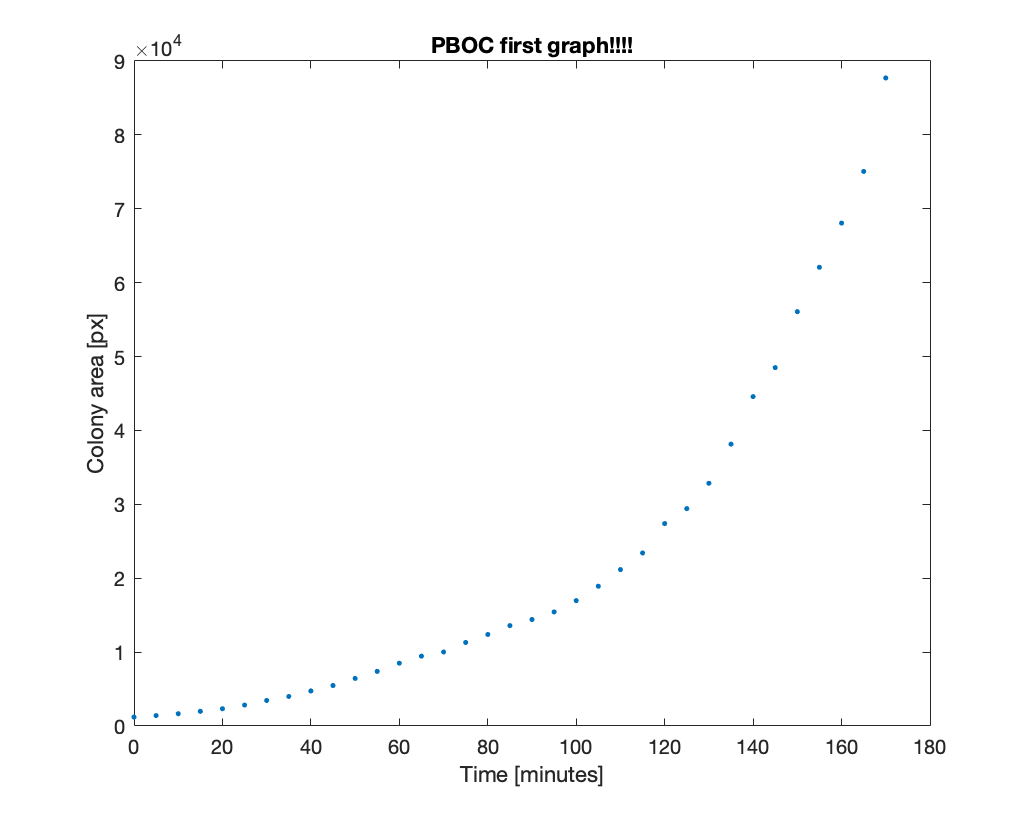

t_frame = 5; % time between frames
time = 0 : t_frame : (length(images)-1)*t_frame;
plot(time, area_list, '.')
xlabel('Time [minutes]'); ylabel('Colony area [px]')
title('PBOC first graph!!!!')

We can export our data in csv format for future use:

outMat = [time' area_list];
csvwrite('Growth_area.csv', outMat);